# lora sim script

## lora parameters

%clear;
SF=12; %spreading factor 7-12
Fs=125e3;%samplingrate = BW
SPS=2^SF;%samples per symbol



## sim parameters

%data
% numSym=round(10000/SF);
numSym=84;

randomData=false;
%channel
perfectChannel=true;%no  awgn
maxDopplerShift=1e3;
flatDoppler=true;%true: apply same shift to entire signal, false: gradient from +maxShift to -maxShift over length of signal
maxSNR=10; %signal to noise ratio in dB
%loops
nLoops=1;
loopSNR=false;
SNRstepsize=2;
loopDoppler=false;
dopplerStepsize=0.1e3;

plotSpectrogram=true;

## tx

%generate data
dataLength=numSym*SF;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    symbol=10;%generate symbols with certain value
    messageBits=transpose(repmat(dec2bin(symbol,SF)-'0',1,numSym));% -'0' to convert binary string to vector
end
%generate lora signal
[loraSignal,decimalSymbols]=generateLoraSignal(messageBits,SF,numSym);
decimalSymbols

decimalSymbols =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


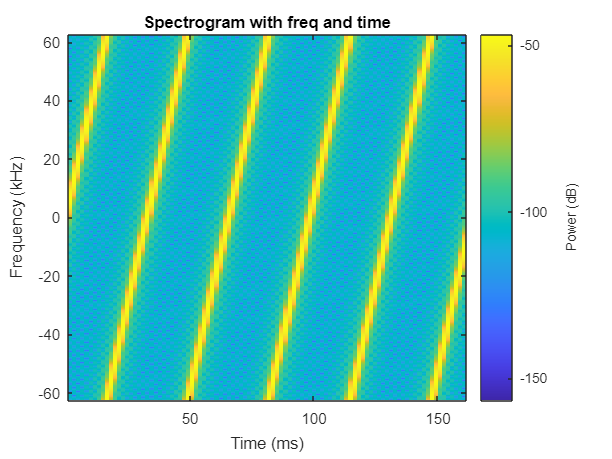

if plotSpectrogram
    %spectroram of first 5 symbols
    figure
    windowLength=round((SPS)/10);
    spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
    title('Spectrogram with freq and time')
    % figure
    % spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
    % title('Spectrogram with freq index and samples')
end

## channel & rx

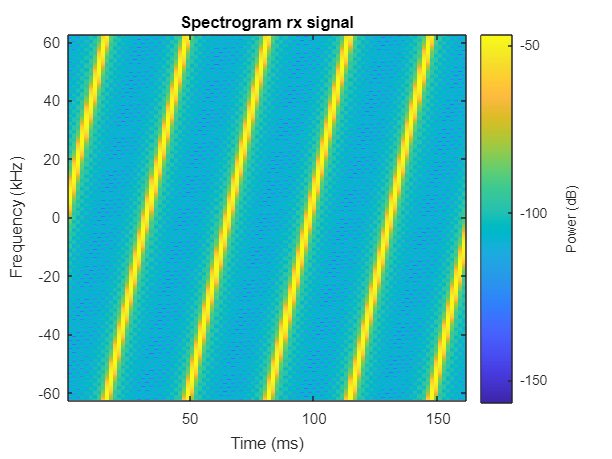

decodedSymbols =     43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43


%channel
for counter=1:nLoops


    symbolDuration=(2^SF)/Fs;

    t=(symbolDuration/2^SF:symbolDuration/2^SF:symbolDuration*numSym);
    
    if flatDoppler
        freqShift=maxDopplerShift;
    else
        freqShift=linspace(-dopplerShift,dopplerShift,length(t));
    end
    dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
    if perfectChannel% use maxDopplerShift = 0 for truly perfect channel
        rxSignal = loraSignal.* (dopplerEffect);
    
    else
        if loopSNR
            rxSignal=(awgn(loraSignal,maxSNR-(counter-1)*SNRstepsize,'measured'));
        else
            rxSignal=(awgn(loraSignal,maxSNR,'measured'));
        end
        %snr
    end

    if (plotSpectrogram && counter==nLoops)
        %spectroram of first 5 symbols
        figure
        windowLength=round((SPS)/10);
        spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
        title('Spectrogram rx signal')
        % figure
        % spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
        % title('Spectrogram with freq index and samples')
    end

    %rx
    [decodedBits,decodedSymbols]=demodulateLoraSignal(rxSignal,SF,numSym);
    decodedSymbols
    errors(counter)=sum(messageBits~=decodedBits);
end

## ber

'Adaptive Parameters for LoRa-Based Networks Physical-Layer' for ber formula

lora_ber=errors/dataLength

lora_ber = 0.1667

lora_ser=sum(transpose(decimalSymbols~=decodedSymbols))/numSym

lora_ser = 1

% lora_ber7=errors/dataLength
% lora_ber9=errors/dataLength
% lora_ber12=errors/dataLength

if loopSNR
    figure
    
    SNRvec=flip((maxSNR-(nLoops-1)*SNRstepsize):SNRstepsize:maxSNR);
    semilogy(SNRvec',lora_ber7,'-*')
    hold on
    semilogy(SNRvec',lora_ber9,'-*')
    semilogy(SNRvec',lora_ber12,'-*')
    %theoryBer12=qfunc((log(SF)/log(12))/sqrt(2)*(SNRvec+10*log10((2^SF)/SF)));
    theoryBer7=qfunc((log(SF)/log(12))/sqrt(2)*(SNRvec+10*log10((2^SF)/SF)));
    semilogy(SNRvec',theoryBer12,'-*')
     semilogy(SNRvec',theoryBer7,'-*')
    grid on
    xlabel('SNR (dB)')
    ylabel('Bit Error Rate')
    ylim([10e-5 1])
    legend('SF 7','SF 9','SF 12','theory 12','theory 7')
    
end


## doppler corection

shifting the signal with n kHz will shift the demodulated symbol with (dopplerShift/BW)*SF

e.g. with SF=7, symbol 0 will be demodulated as 66 when the signal is shifted with 64 kHz 

original symbol = received symbol -(dopplerShift/125kHz)*SF)

to estimate frequency shift: ((receivedSymbol-expectedSymbol)/SF)*BW